# 多元多项式拟合问题

### 1. 一元多项式拟合

介绍两种方法：调用系统函数 polyfit ，左除的方法。两种方法结果一致，查看 polyfit 帮助文档，polyfit 函数实际上使用的算法就是左除。

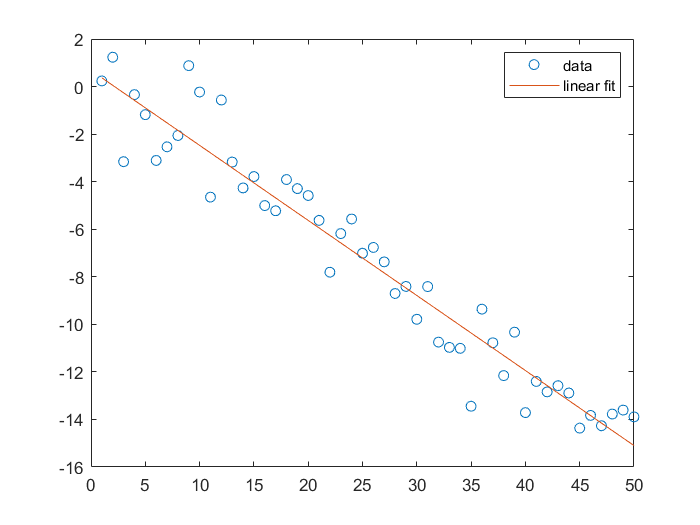

clear;clc;close all;
% 产生拟合数据
rng('default');
x = 1:50; 
y = -0.3*x + randn(1, 50); 
% 用 1 次多项式来拟合
p = polyfit(x, y, 1);
% 计算拟合值
y1 = polyval(p, x);
% 绘图
plot(x,y,'o', x, y1)
legend('data','linear fit') 

% 用左除的方法
p1 = [x', ones(length(x), 1)] \ y';
% 结果对比
disp(num2str(1000000*[p; p1']));

-315639.9914      682855.3273
-315639.9914      682855.3273


### 2. 二元多项式拟合

基于一元多项式拟合的左除方法，进一步推广到二元多项式拟合，对比左除法和调用系统函数 lsqcurvefit 结果。

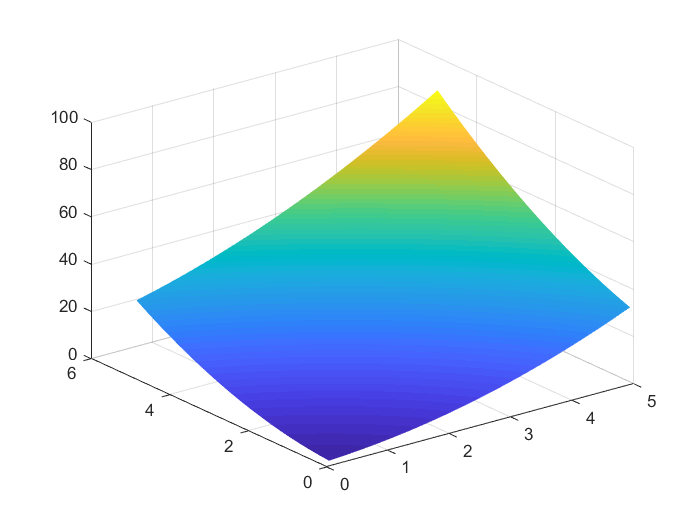

clear; clc; close all;
% 曲面方程：f(x,y) = a20*x.^2 + a02*y.^2 + a11*x.*y +  a10*x + a01*y + a00
x = 0.1 : 0.1 : 5;
y = 0.1 : 0.1 : 5;
[X, Y] = meshgrid(x, y);
% 建立曲面模型，假设未知参数都是 1
Z = X.^2 + Y.^2 + X.*Y + X + Y + 1;
% 绘制模型曲面
surf(X, Y, Z);
shading interp

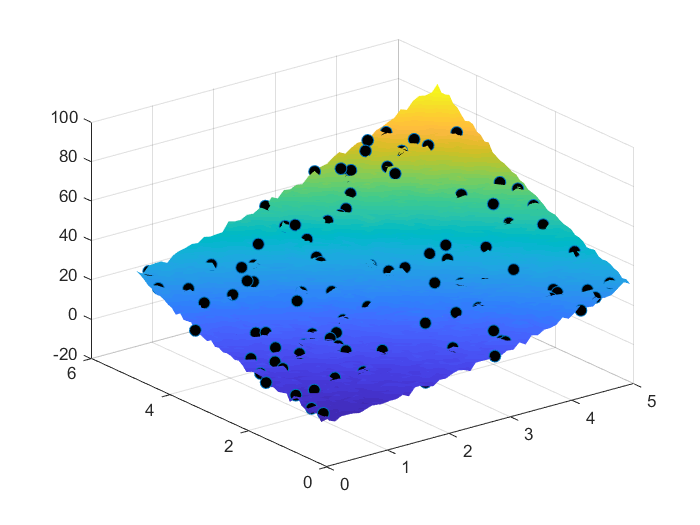

% 添加噪声
rng('default');
ratio = 1;
Z1 = Z + ratio*randn(size(Z));
% 随机选择 100 个点来做拟合
xPos = randi(50, 100, 1);
yPos = randi(50, 100, 1);
xfit = x(xPos)';
yfit = y(yPos)';
zfit = zeros(100, 1);
for i = 1:100
    zfit(i) = Z1(xPos(i), yPos(i));
end
% 绘制带有噪音的模型曲面和用来拟合的离散点
surf(X, Y, Z1);
shading interp
hold on 
scatter3(xfit, yfit, zfit, 50, 'MarkerFaceColor', [0 0 0]);
hold off

% 两种方式求解
% 1. 用 lsqcurvefit 函数求解
func = @(var,x) var(1)*x(:,1).^2 + var(2)*x(:,2).^2 + var(3)*x(:,1).*x(:,2) + var(4)*x(:,1) + var(5)*x(:,2) + var(6);
val = lsqcurvefit(func, rand(1, 6), [xfit, yfit], zfit);


Local minimum possible.

lsqcurvefit stopped because the size of the current step is less than
the default value of the step size tolerance.

<stopping criteria details>



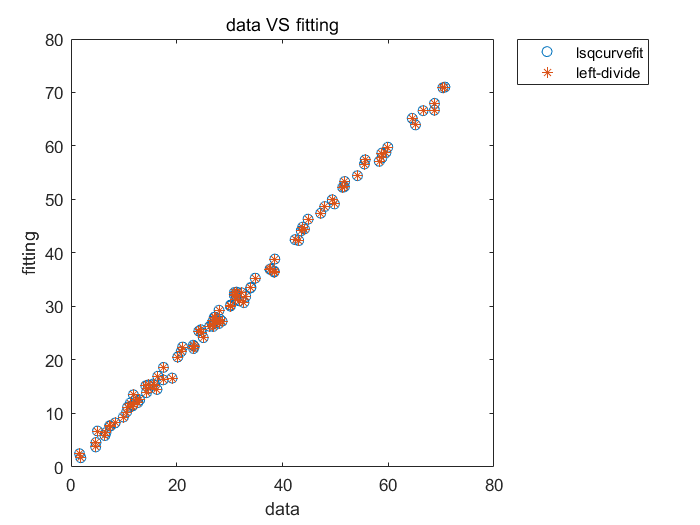

% 拟合值
zFit = func(val, [xfit, yfit]);
% 2. 用左除的方法求解
xfit2 = xfit.^2;
yfit2 = yfit.^2;
xyfit = xfit.*yfit;
A = [xfit2, yfit2, xyfit, xfit, yfit, ones(100, 1)];
val2 = A \ zfit;
% 拟合值
zFit2 = func(val2, [xfit, yfit]);
% 绘制拟合点结果
plot(zfit, zFit, 'o', zfit, zFit2, '*');
legend('lsqcurvefit', 'left-divide')
xlabel('data');
ylabel('fitting');
title('data VS fitting');

% 结果对比
disp(num2str(1000000*[val; val2']));

983945.44992      919574.49832      1059015.6444      968659.89215      1276751.8776      759443.62574
983945.46936      919574.48579      1059015.6413      968659.83371      1276751.9467      759443.58615
